clear all
close all

addpath('classes')

### Simulation

dt = 0.5

dt = 0.5000

t_end = 25

t_end = 25

t = 0:dt:t_end

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000



x0 = [1;1;0];


robot_num = 3;
robot_set = repmat(Robot.empty, robot_num, 1);

for j = 1:robot_num
    x0 = [  -1 + 2*rand;
            -1 + 2*rand;
            -pi + 2*pi*rand;]

    robot_set(j) =  Robot(x0);
end

x0 =    -0.4367
   -0.0382
    1.1615


x0 =    -0.5835
    0.2163
   -1.0922


x0 =     0.7617
   -0.7332
   -2.4981



for i = 1:length(t)
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update(dt);
    end
end


### Graphs

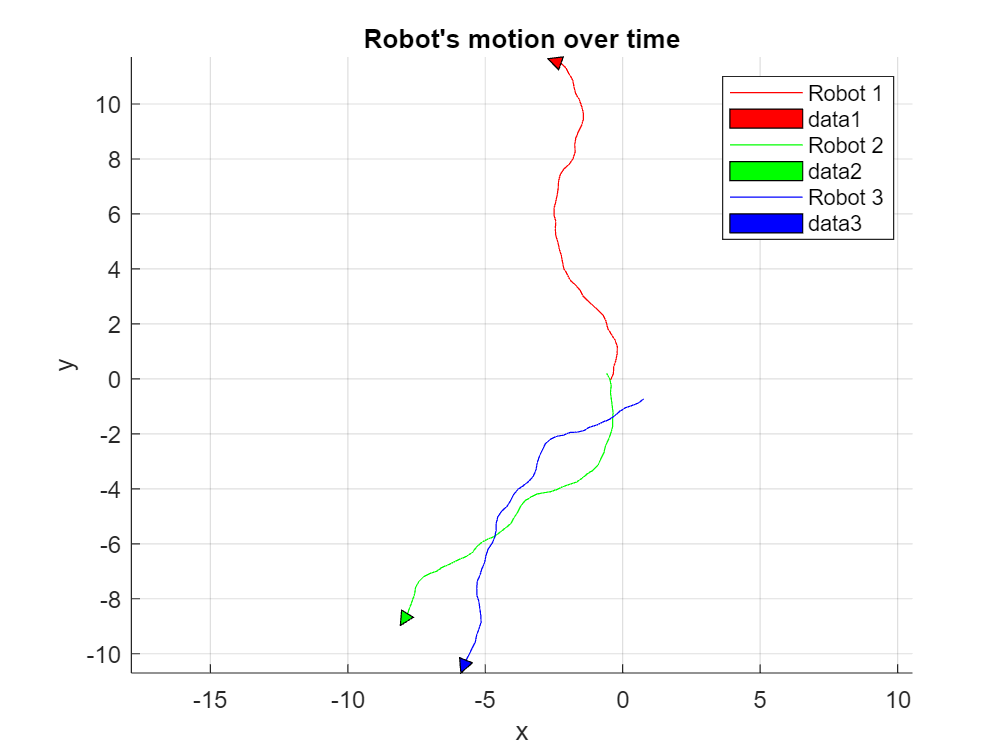

figure;

myColormap = hsv(robot_num);

hold on; axis equal;
for j = 1:robot_num
    plot(robot_set(j).true_Path(:,1), robot_set(j).true_Path(:,2), 'Color', myColormap(j,:), 'DisplayName', sprintf('Robot %d', j));
    triangle = robot_set(j).get_triangle;
    patch(triangle(1,:), triangle(2,:), myColormap(j,:));
end


xlabel('x');
ylabel('y');
title("Robot's motion over time");
legend;
% border_value = 10
% xlim([-border_value border_value])
% ylim([-border_value border_value])
grid on; hold off